## Raman spectra analysis

Written by Thomas Dixon on 06/05/2021

Designed by Rachel Bocking and Thomas Dixon

This code provides a template that will allow you to perform routine data analysis on raman data. The code is configured to calculate the height ratios of two peaks. By providng the regon in which the peaks occur, the script can caculate the heights as well as the ratios of the peak heights for multiple spectra at the same time, and then plot the data as a nicely labeled graph of all the spectras. It will also save the data to seperate excel sheets incase you want to do the plots on excel.

Note the code in the 'PeakFinder' folder was not written by me. It is used to fit the peaks to a lorentz curve, to identify the two largest peaks in teh spectra. You can find out more detial about this via this link: [https://terpconnect.umd.edu/~toh/spectrum/PeakFindingandMeasurement.htm#findpeaks](https://terpconnect.umd.edu/~toh/spectrum/PeakFindingandMeasurement.htm#findpeaks)

Please follow the instructions bellow on how to use the software. Works on matlab 2020b.

Thanks :)

## Step 1: Clear prevous output and add file paths

Change the file path so that it can find the files contained inside 'PeakFinder'. Make sure the output on the RHS is cleared by right clicking on the output and selecting 'Clear All Output'. Then press 'run section' and move on to next step.

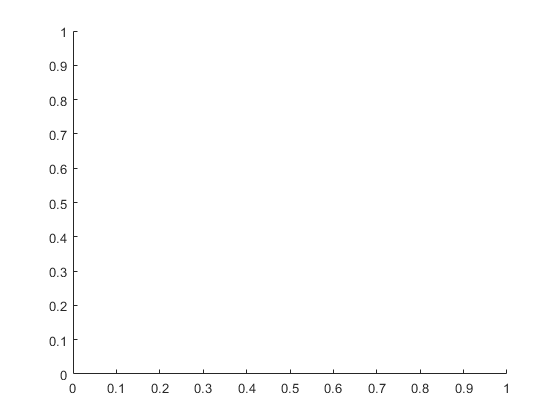

clear
clc
cla reset

addpath("PeakFinder")

## Step 2: Modify the parameters of the data analysis

To fine tune your data analyis, modify the parameters below. Then press 'run section' and move on to next step.

% In the string array 'fileNames', enter the names of 
% each file you would like to be analysed in the format 
% "XXX.txt" each seperated by a comma (like in the 
% example shown). Each file must be in the same directory as the code
% files.
params.fileNames = ["Run 1","Run 2","Run 3", "Run 4", "Run 5"];

% Corrispond each entry in 'fileNames' with a legend 
% name in 'legNames' in the same way. This is the name 
% that is displayed on the final graph plot.
params.legNames = ["Graph 1", "Graph 2", "Graph 3", "Graph 4", "Graph 5"];

%This setting is for error checking. When 'showMax = true', lines on the
%plot indicate where the algorithm has detected the two maximum peaks to
%calculate the ratio. It also shows how well a 
params.showMax = false;

params.baselineShift = 30; %Modifes how much of a gap there is between each spectra
params.xAxisLim = [1000, 2000]; %Sets the X axis limits
params.calcTextXShift = 1800; %Sets the X axis value for the ratio calculation variable
params.lineWidths = 2; %Alters the line width of the graphs
params.maxNormIntensity = 100; %Varies the maximum normlised intensity
params.xaxisLabel = "Raman shift / cm^{-1}"; %Modifiy the x axis label
params.yaxisLabel = "Normalised Intensity"; %Modify the y axis label
params.labelName1 = "X"; %Modify the peak 1 label name
params.labelName2 = "Y"; %Modify the peak 2 label name
params.labelPosX1 = 1350; %Modify the peak 1 label x pos
params.labelPosX2 = 1600; %Modify the peak 2 label x pos
params.labelShiftY = 120; %Modify peak 1 and 2 label y pos above the top curve

%Enter the limits of the two peaks you are interested in.
%The first limit (lim1) is the limits [min, max] of the first peak (LHS peak) 
%and the second limit (lim2) is the limits [min, max] of the second peak
%(RHS peaks).

params.lim1 = [1300, 1400];
params.lim2 = [1450, 1650];

%These paramters alter the way the Lorentzian peak
%finding algorithm works. Alter the [SlopeThreshold,AmpThreshold,
%smoothwidth,peakgroup,smoothtype,window,PeakShape,extra,NumTrials,AUTOZERO]
%This webisite: 
%(https://terpconnect.umd.edu/~toh/spectrum/PeakFindingandMeasurement.htm#findpeaks)
%explains in detail what each of this paramters does, but these settings
%should be fine.

params.lorenzParams = [0.01,20,20,10,3,100,2,0,0,0];

%These varables determine the value of the cluster size calculation, which
%uses the ratio of the two peaks. The equation used in this example is:
% L = C*lambda^4*(ID/IG)^-1. Where ID/IG is the ratio calaculted by the code.

params.C = 2.4e-10;
params.lambda = 532;


## Step 3: Run the analysis to generate the plot

Runs the analysis code and then saves all the data as a .mat file. Then press 'run section' and move on to next step.

X-axis flipped.
X-axis flipped.
X-axis flipped.
X-axis flipped.
X-axis flipped.
X-axis flipped.
X-axis flipped.
X-axis flipped.
X-axis flipped.
X-axis flipped.


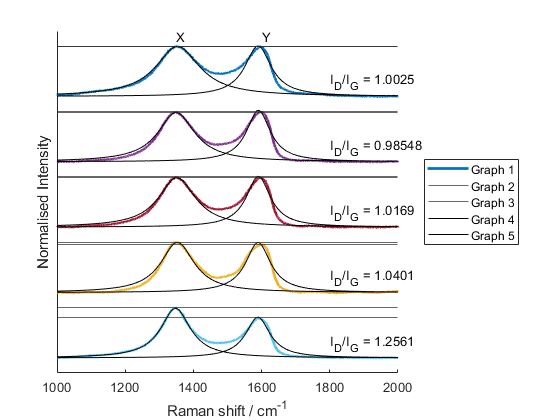

%Runs the analysis and plots the graph given the parameters
data = plotGraphs(params);

save ramanData.mat data


## Step 4: Write the data to an Excel file

This step writes each output of the .txt files to a seperate Excel document. Sheet 1 contains the raw and proccessed data where as sheet 2 contains infomation about the height of the two maximum peaks, their ratio as well as the cluster size and the file name. Then press 'run section' and make sure the excel files open as expected.

%Enter name of the folder you want to save these files too (will create a
%new one if it does not already exist)
directory = "allData"

%Makes a directory (if it does not already exist) to store the data in.
mkdir(directory)

%Loops through each data file that has been read
for graph = 1:size(data,1)
    
    %Sets the file name the same as the .txt file.
    filename = directory + "\"+ data{graph,7} + '.xlsx';
    
    %Concatinates the raw data and modified data and adds it to a table
    %format to add the data to the excel file. Change the title names as 
    %desired in the 'array2table' function.
    allData = [data{graph,1} data{graph,2}];
    T = array2table(allData,"VariableNames",["Wavenumber", "Intensity", "WavenumberProcessed","IntensityProcessed"]);
    
    %Concatinates the extracted values from the modifed graph data and adds
    %it to a table format to add the data to the excel file. Change the 
    %title names as desired in the 'array2table' function.
    values = [data{graph,3} data{graph,4} data{graph,5} data{graph,6} data{graph,7} data{graph,8}, data{graph,9}];
    T2 = array2table(values,"VariableNames",["D","G","ratio","Clussize","filename", "D_width","G_width"]);
    
    %Writes each table generated to a seperate sheet. Change the sheet
    %numer if desired.
    writetable(T,filename,'Sheet',1);
    writetable(T2,filename,'Sheet',2);
end


function data = plotGraphs(params)
    
    % Creates a cell to store all the data in
    data = cell(length(params.fileNames), 6);
    
    % Loops through each filename, imports and then processes the data. Adds it
    % all to the cell 'data'.
    for graph = 1:length(params.fileNames)
        [orgData, newData, D, G, P, ratio, clusSize] = processData(params.fileNames(graph), params);
        data{graph,1} = orgData; %Orginal (unprocessed) data
        data{graph,2} = newData; %Processed data
        data{graph,3} = D; %Y pos of the D peak (LHS peak)
        data{graph,4} = G; %Y pos of the G peak (RHS peak)
        data{graph,5} = ratio; % Ratio of intensity of D/G (LHS/RHS)
        data{graph,6} = clusSize; % Cluster size based on equation
        data{graph,7} = params.fileNames(graph); %Specific file name
        data{graph,8} = P(1,4); %Width of peak 1
        data{graph,9} = P(2,4); %Width of peak 2
        data{graph,10} = P(1,2); %X value of peak 1
        data{graph,11} = P(1,3); %Y value of peak 1
        data{graph,12} = P(2,2); %X value of peak 2
        data{graph,13} = P(2,3); %Y value of peak 2
    end
    
    % Calculates the shifts the graphs need to stack on top of one another
    shifts = 1:length(params.fileNames);
    shifts = flip((shifts-1)*params.maxNormIntensity + (params.baselineShift.*shifts)); % Matrix containing each shift of each graph in order
    
    ax1 = gca; % Sets up the axis
    set(ax1,'ytick',[]); % Removes the labels on the Y axis (so it is unitless)
    
    xlim(ax1, [params.xAxisLim(1), params.xAxisLim(2)]) % Sets the X limit range
    ylim(ax1, [0 shifts(1)+params.maxNormIntensity+params.baselineShift]) % Sets the Y limit range
    xlabel(ax1, params.xaxisLabel) % X axis label
    ylabel(ax1, params.yaxisLabel) % Y axis label
    
    % Goes through each graph and plots it along with the ratio data
    for graph = 1:length(params.fileNames)
        hold on %Overaly each graph
        
        %Plot the graph given the Y shifts caluclated and the line width
        %stated.
        plot(data{graph,2}(:,1), data{graph,2}(:,2)+shifts(graph),"LineWidth",params.lineWidths);
        
        %When true, this error checks the graph plotted by showing the
        %maximum values of each peak detected as well as plots the lorentz
        %curve to see how well it fits
        if params.showMax == true
            yline(data{graph,3}+shifts(graph)); %Max Y line for D peak (LHS)
            yline(data{graph,4}+shifts(graph)); %Max Y line for G peak (RHS)
            
            % Sets up a series of 1000 points between the axis limits to
            % plot the lorentz curve.
            points = linspace(params.xAxisLim(1),params.xAxisLim(2),1000);
            
            %Plot lorentz curve for D peak (LHS)
            plot(points, lorentz(points,data{graph,10},data{graph,8}/2,data{graph,11})+shifts(graph), "k-");
            
            %Plot lorentz curve for G peak (RHS)
            plot(points, lorentz(points,data{graph,12},data{graph,9}/2,data{graph,13})+shifts(graph), "k-");
        end
        
        %Writes the text that displays the ratio next to the curves.
        str = "I_{D}/I_{G} = " + string(data{graph,5});
        %Plots the text next to the curve.
        text(params.calcTextXShift, shifts(graph)+30,str);
        
        hold off %Stops  more overlay
    end
    
    % Adds D and G lables at the top of the peaks
    text(params.labelPosX1, shifts(1)+params.labelShiftY,params.labelName1);
    text(params.labelPosX2, shifts(1)+params.labelShiftY,params.labelName2);
    
    % Adds the legend. Modfiy this if you want to change where the ledgend
    % goes.
    legend(ax1, params.legNames, "Location", "eastoutside");

end


%This function processes the data by finding the largest value present to
%normalise the data; finds the maximum value of two peaks between the
%ranges specified and calculates their ratio; and fits peaks to a lorentz
%function so that the peak width can be estimated.
function [rawData, processedData, D, G, P, ratio, clusSize] = processData(txtFile, params)
    %Import data
    rawData = readtable(txtFile);
    
    %Convert to array
    rawData = table2array(rawData);
    
    %Create a copy to process
    processedData = rawData;
    
    %Find max value
    maxVal = max(processedData(:,2));
    
    %Normalize
    processedData(:,2) = (processedData(:,2)./maxVal)*params.maxNormIntensity;
    
    % Fit peak to a lorentz function. Code from:
    % https://terpconnect.umd.edu/~toh/spectrum/PeakFindingandMeasurement.htm#findpeaks
    P = findpeaksb(processedData(:,1),processedData(:,2),...
        params.lorenzParams(1),params.lorenzParams(2),params.lorenzParams(3),...
        params.lorenzParams(4),params.lorenzParams(5),params.lorenzParams(6),...
        params.lorenzParams(7),params.lorenzParams(8),params.lorenzParams(9),...
        params.lorenzParams(10));
    
    %Sorts the rows in increasing order on the X axis so that the LHS peak is the first 
    %entry and the RHS peak is the second 
    P = sortrows(P,2,"ascend");

    % Temp data assignment to processed data make the code easier to read
    limY = processedData(:,2);
    limX = processedData(:,1);
    
    % Searches for the D (LHS) peak in the specified regon and selects the largest
    % value in this regon (peak max)
    lim1 = and(limX > params.lim1(1), limX < params.lim1(2));
    lim1Y = limY(lim1);
    D = max(lim1Y);
    
    % Searches for the G (RHS) peak in the specified regon and selects the largest
    % value in this regon (peak max)
    lim2 = and(limX > params.lim2(1), limX < params.lim2(2));
    lim2Y = limY(lim2);
    G = max(lim2Y);
    
    % Calculates the ratio of the intensities of D/G
    ratio = D/G;
    
    % Cluster size calcaution using the ratios calculated above 
    clusSize = 2.4e-10*(532^4)*(1/ratio);
end

function y = lorentz(x, position, half_width_half_max, height)
    % A function to plot a Lorentzian (a.k.a. Cauchy) distribution given a
    % space vector 'x', a position and a half width at half maximum.
    % The distribution is then scaled to the specified height.
    if nargin <=2
        errordlg(["At least three input arguments are required.";...
            "These must be in the order x_space, position, half_width.";...
            "An extra height argument can be added to change scale."],...
            "Input Error")
    end
    y = 1 ./ (half_width_half_max.*...
        (1+((x-position)./half_width_half_max).^2));
    
    if nargin == 3
        height = max(y);
    end
    
    y = y.*(height/max(y));
    
end